# Data Analysis (Trajectory analysis)

Trajectory data analysis for Obstacle Avoidance Project Written by PAK (August2018)

## Load the file

in this section, the initially marked data should be selected for more analysis.

In the first 

[filename,pathname] = uigetfile('*.mat','Please choose the DataSet you want to load...');
cd(pathname);
% trn = 1;
FILES = filename;
leng = length(filename);

if exist([filename(1:leng-4) '.mat'],'file') == 2         
    if contains(filename,'marked')
        load([filename(1:leng-4) '.mat']);
    end
end

## Intropolation (increase sampling rate to 120Hz), Filtering, ON-OFF calculation, Velocity and Acceleration calculation

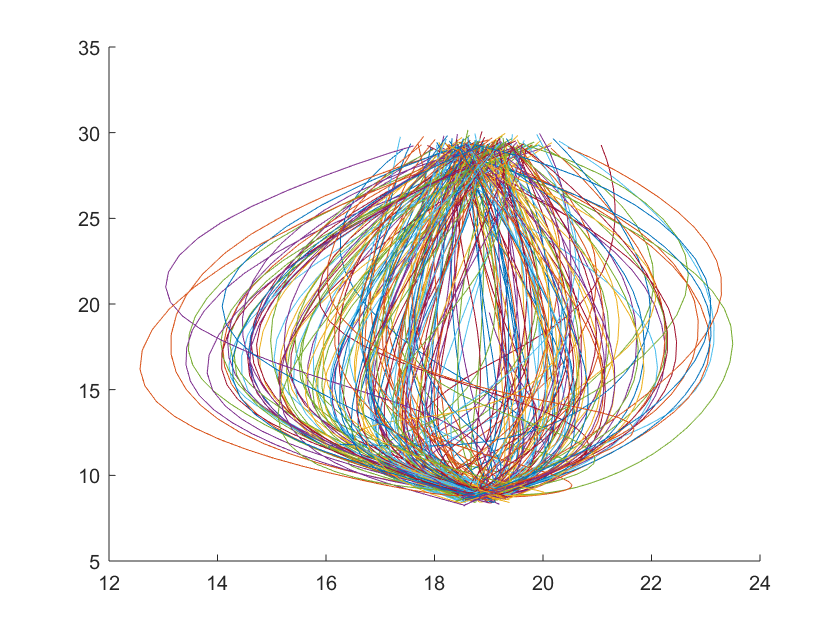

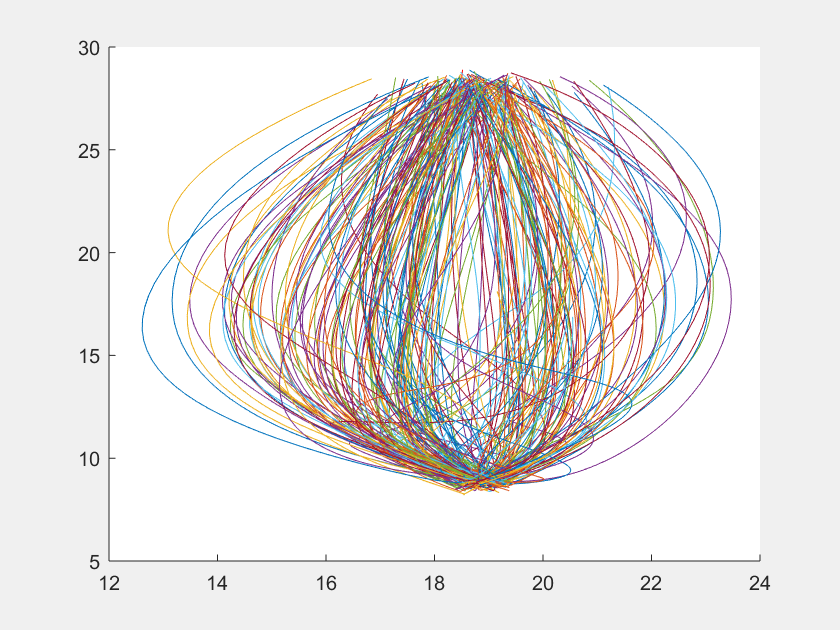

figure(1); hold on
for i = 1 : D.trialnum
    tON = D.eventtime{i}(2); % time of target presentation
    %ton = find(D.t{i}(:) >= tON, 1 ); 
    tEM = D.handOFF{i}; % End of movement (targethit/collision)
    %tem = find(D.t{i}(:) >= tEM, 1 ); 
    Rarr = find(D.t{i} >= tON, 1 ):find(D.t{i} <= tEM, 1, 'last' );
    sr = length(Rarr) / (tEM - tON);
    x = nan(length(Rarr)*2-1,2);
    x(1:2:end,:)= D.handscreen{1,i}(Rarr(1):Rarr(end),:);
    % intropolate to find the missing data points
    xint = inpaint_nans(x,2);
    figure(1); plot(xint(:,1),xint(:,2))
    
    % Low-pass filtering (to remove noise)
    sfr = sr * 2;
    cutoff = 50;
    handx = GRAIautoregfilt(sfr,cutoff,xint(:,1));
    handy = GRAIautoregfilt(sfr,cutoff,xint(:,2));
    figure(2); hold on; plot(handx,handy)
    
    % Velocity Calculation
    handXv = GRAIdiff(1/sfr,win,handx);
    handYv = GRAIdiff(1/sfr,win,handy);
    
    % Acceleration Calculation
    handXa = GRAIdiff(1/sfr,win,handXv);
    handZa = GRAIdiff(1/sfr,win,handYv);
    
    % ON-OFF calculations
    
    
end

## Normalization

## Standardization (removing a baseline from trajectories)

## Calculate different parameters